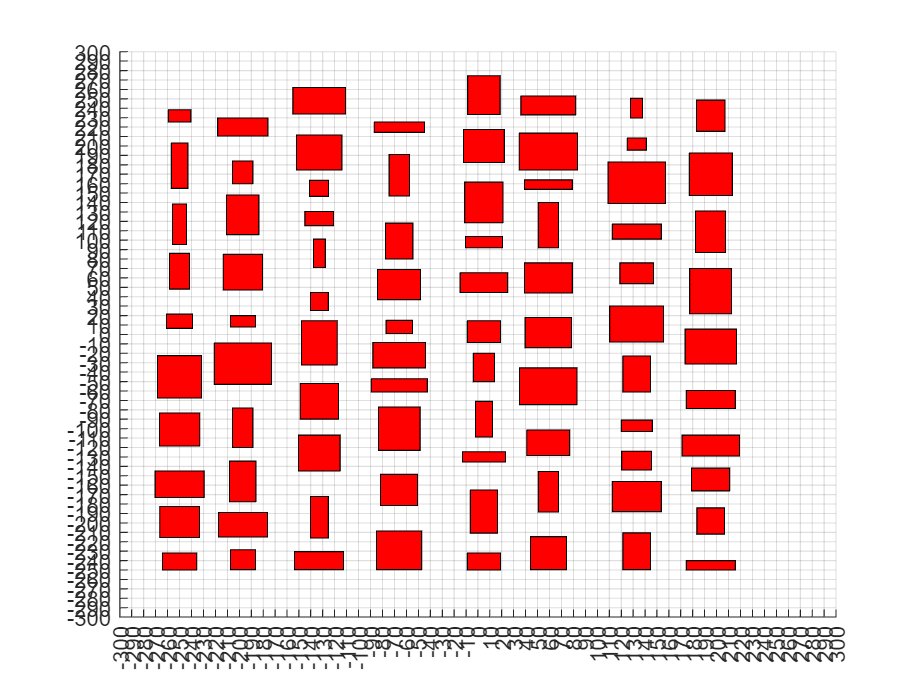

file = fopen("test22.wc","r");

first_line = fgetl(file);
world_size_line = split(first_line);
world_size = str2double(world_size_line);

world = ones([world_size(1)*2 world_size(2)*2]);
figu = figure;

while ~feof(file)
    file_line = fgetl(file);
    building_line = split(file_line);
    building = str2double(building_line);
    
    b_size = [building(4) building(5) building(6)];
    start_bound = [(building(1)-b_size(1)/2) (building(2)-b_size(2)/2)];
    %end_bound = [(building(1)+b_size(1)/2) (building(2)+b_size(2)/2)]
    
    mat_init = pos2matind(start_bound);
    mat_end = pos2matind(start_bound + b_size(:,1:2)) - [1 1];
    world(mat_init(1):mat_end(1), mat_init(2):mat_end(2)) = zeros(b_size(1:2)*2);

    rectangle('FaceColor', 'red', 'Position',[start_bound,b_size(:,1:2)])
end
fclose(file);

xlim([-world_size(1)/2 world_size(1)/2])
ylim([-world_size(2)/2 world_size(2)/2])
xticks([-world_size(1)/2:10:world_size(1)/2])
yticks([-world_size(2)/2:10:world_size(2)/2])
grid on

pos = [-100 0];
posmat = pos2matind(pos)
world(posmat(1),posmat(2))

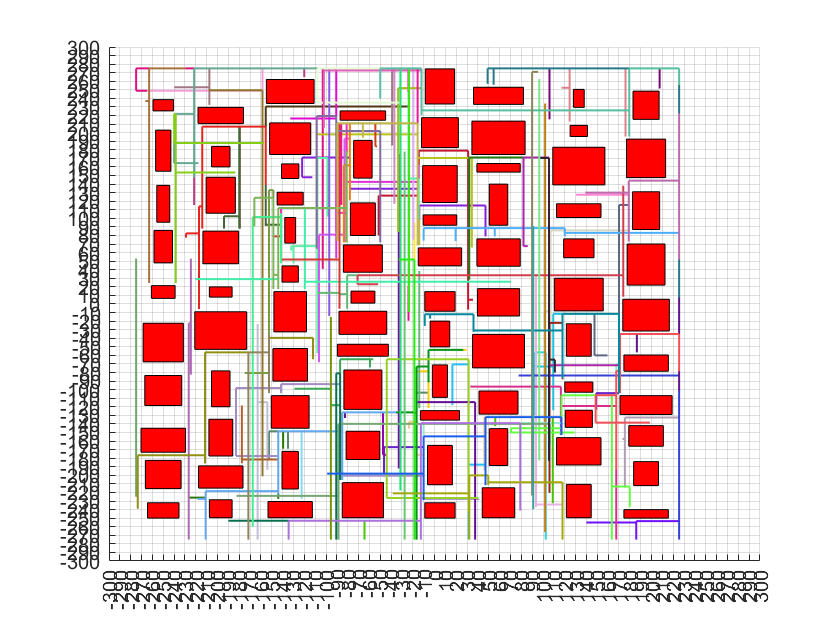

rutas = 0;

while rutas < 100
    while 1
        pos = randomMatInd();
        if hasClearAround(world, pos, 6)
            break;
        end
    end
    route = [pos];
    waypoints = [];
    dist = 0;
    finish = 0;
    dir = -1;

    while ~finish
        waypoints(end+1,:) = matind2pos(pos);
        keep_straight = 1;
        if dir == -1
            dir = randi([0 3]);
        else
            dir = mod(dir,3) + 1;
        end
        step = getStep(dir);

        while ~finish && keep_straight
            next_pos = pos + step;
            if hasClearAround(world, next_pos, 6) ...
                    && next_pos(1) >= 50 && next_pos(1) <= 1051 && next_pos(2) >= 50 && next_pos(2) <= 1150
                if check(world, next_pos)
                   dist = dist + 1;
                   if dist >= 1000
                       finish = 1;
                   end
                   pos = next_pos;
                   pos_real = matind2pos(pos);
                   route(end+1,:) = pos;

                   change_change_dir = rand();
                   if change_change_dir < 0.002
                        keep_straight = 0;
                   end
                else
                    keep_straight = 0;
                end
            else
                keep_straight = 0;
            end
        end
    end
    waypoints(end+1,:) = matind2pos(pos);
    rutas = rutas + 1;
    
    i = 1;
    route_real = [];
    while i <= size(route,1)
        r = matind2pos(route(i,:));
        route_real(end+1,:) = r;
        i = i + 1;
    end
    line(route_real(:,1)', route_real(:,2)', 'Color', rand(1,3), 'LineWidth', 1);
    drawnow;
    %pause(0.2);
end

matind2pos(route(1,:));

function ret = pos2matind(pos)
    ret = [pos(1)*2+600 pos(2)*2+600];
end

function ret = matind2pos(pos)
    ret = [(pos(1)/2)-300 (pos(2)/2)-300];
end

function ret = randomMatInd()
    ret = [randi([0 1200]) randi([0 1200])];
    ret = [randi([50 1000]) randi([50 1150])];
end

function ret = check(world, pos)
    ret = world(pos(1),pos(2));
end

function ret = hasClearAround(world, pos, dist)
    if check(world, pos + [0 dist]) && check(world, pos + [0 -dist]) && check(world, pos + [dist 0]) && check(world, pos + [-dist 0]) ...
            && check(world, pos + [dist dist]) && check(world, pos + [-dist -dist]) && check(world, pos + [dist -dist]) && check(world, pos + [-dist dist])
        ret = 1;
    else
        ret = 0;
    end
end

function step = getStep(dir)
    switch dir
        case 0
            step = [-1 0];
        case 1
            step = [0 1];
        case 2
            step = [1 0];
        case 3
            step = [0 -1];
    end
end